# 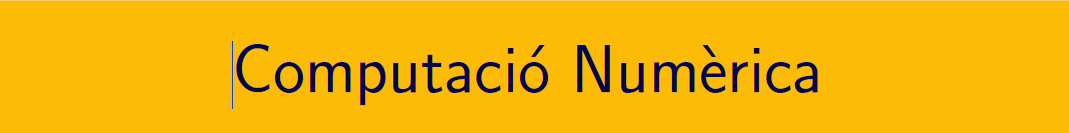

================================================================================

# Pràctica 13. Equacions diferencials ordinàries (III).

`Document preparat per M. Àngela Grau Gotés - 24 de maig de 2023`

## Mètodes d'un pas implícits i  explícits

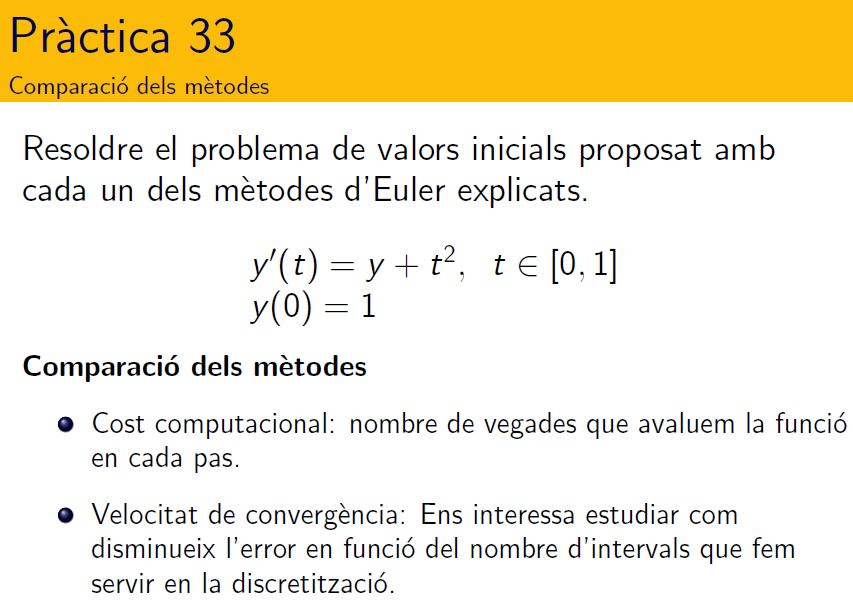

syms y(t)
eqn = diff(y,t) == t^2+y;
cond = y(0) == 1;
ySol(t) = dsolve(eqn,cond)

$$ySol(t) = 3\,{\mathrm{e}}^{t}-2\,t-t^{2}-2$$

#### APROXIMACIONS NUMERIQUES

f = @(t,y) (t.^2 + y)

f = function_handle with value:
    @(t,y)(t.^2+y)


a = 0; b = 1; alpha = 1;
h = 0.01;    
[ wE,t1 ] = Euler(f,a,b,h,alpha);         % nombre d'evaluacions h
[ wEmod,t2 ] = EulerMod(f,a,b,h,alpha);   % nombre d'evaluacions h^2
[ wHeun,t3 ] = Heun(f,a,b,h,alpha);       % nombre d'evaluacions h
[ wRK4,t4 ] = RK4(f,a,b,h,alpha);         % nombre d'evaluacions h^4


error_glob_E = double(abs(wE(end)- ySol(b)))

error_glob_E = 0.0234

error_glob_Emod = double(abs(wEmod(end)- ySol(b)))

error_glob_Emod = 9.2155e-05

error_glob_Heun = double(abs(wHeun(end)- ySol(b)))

error_glob_Heun = 4.9413e-05

error_glob_RK4 = double(abs(wRK4(end)- ySol(b)))

error_glob_RK4 = 3.1774e-10

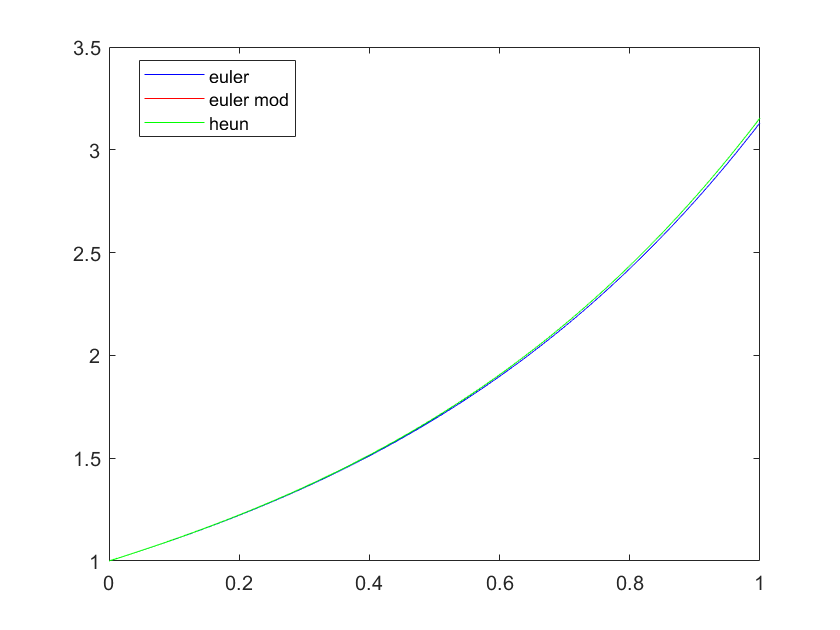


plot(t1,wE,'b')
hold on
plot(t2,wEmod, 'r')
plot(t3,wHeun,'g')
hold off
legend('euler','euler mod', 'heun', 'Location',"best")

#### CODIS AUXILIARS

function [ w,t ] = Euler(f,a,b,h,alpha)
% Mètode d'Euler
t=[a:h:b];
N=length(t);
w(1)=alpha;
for i=1:N-1
    w(i+1)=w(i)+h*f(t(i),w(i));
end
end
%-----------------------------------------
function  [w,t]  = EulerMod( f,a,b,h,alpha )
% Mètode d'Euler Modificat o punto medio
t=[a:h:b];
N=length(t);
w(1)=alpha;
for i=1:N-1
    k1 = w(i)+0.5*h*f(t(i),w(i) );
    w(i+1)=w(i)+h*f(t(i)+ h/2,k1);
end
end
%-----------------------------------------
function  [w,t]  = Heun( f,a,b,h,alpha )
% Mètode d'Euler Millorat o HEUN
    t=[a:h:b];
    N=length(t);
    w(1)=alpha;
    for i=1:N-1
        k1 = h*f(t(i),w(i) );
        k2 = h*f(t(i+1),w(i) +k1);
        w(i+1)=w(i)+0.5*(k1+k2);
    end
end
%----------------------------------------
function  [w,t]  = RK4( f,a,b,h,alpha )
% Mètode RK4
    t=[a:h:b];
    N=length(t);
    w(1)=alpha;
    for i=1:N-1
        k1 = h*f(t(i),w(i));
        k2 = h*f(t(i)+h/2,w(i) +k1/2);
        k3 = h*f(t(i)+h/2,w(i) +k2/2);
        k4 = h*f(t(i+1),w(i) +k3);
        w(i+1)=w(i)+(k1+2*k2+2*k3+k4)/6;
    end
end